- **FIGURA 3.10(c)**

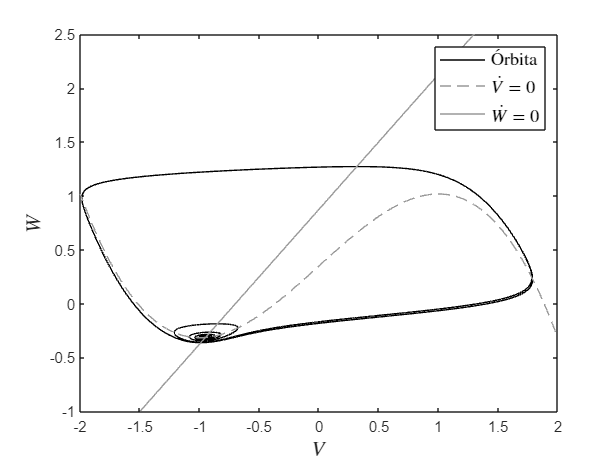

ta = 1000; n = 1000000; a = 0.7; b = 0.8; I = 0.35; phi = 0.08; y0 = [-0.9515; -0.3143];
f = @(y) [y(1) - y(1).^3 / 3 - y(2) + I; 
          phi * (y(1) + a - b * y(2))];
[~, y] = rk4(f, ta, y0, n);

h1 = plot(y(1, :), y(2, :), 'k'); 

hold on; 

y1_vals = linspace(min(y(1, :)) - 1, max(y(1, :)) + 1, 100000); 
y2_f1 = y1_vals - (y1_vals.^3 / 3) + I;
y2_f2 = (y1_vals + a) / b;

h2 = plot(y1_vals, y2_f1, '--', 'Color', [0.6, 0.6, 0.6]); 
h3 = plot(y1_vals, y2_f2, 'Color', [0.6, 0.6, 0.6]); 

xlim([-2, 2]);
ylim([-1, 2.5]);

xlabel('$V$', 'Interpreter', 'latex', 'FontSize', 14); 
ylabel('$W$', 'Interpreter', 'latex', 'FontSize', 14);

legend([h1, h2, h3], {'\''{O}rbita', '$\dot{V} = 0$', '$\dot{W} = 0$'}, 'Interpreter', 'latex', 'FontSize', 12);

hold off;

- **FIGURA 3.11(c)**

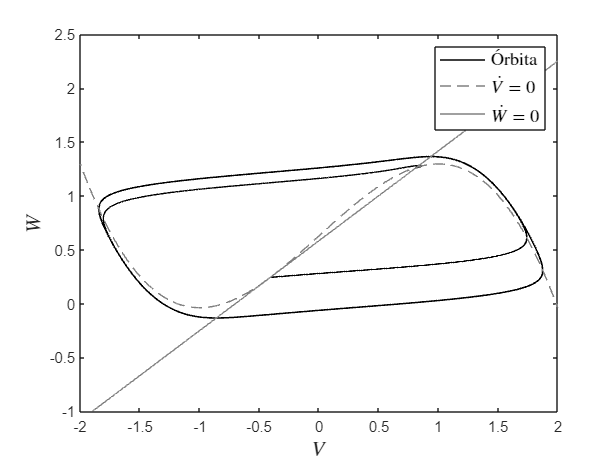

ta = 1000; n = 1000000; a = 0.7; b = 1.2; I = 1170/1861; phi = 0.08; y_0 = [-0.4082; 0.24310]; y_1 = [0.8165; 1.2637];
f = @(y) [y(1) - y(1).^3 / 3 - y(2) + I; 
          phi * (y(1) + a - b * y(2))];
[~, y0] = rk4(f, ta, y_0, n);
[~, y1] = rk4(f, ta, y_1, n);

plot(y0(1, :), y0(2, :), 'k', 'LineWidth', 1.1); 

hold on;

h1 = plot(y1(1, :), y1(2, :), 'k'); 

y1_vals = linspace(min(y0(1, :)) - 1, max(y0(1, :)) + 1, 10000); 
y2_f1 = y1_vals - (y1_vals.^3 / 3) + I;
y2_f2 = (y1_vals + a) / b;

h2 = plot(y1_vals, y2_f1, '--', 'Color', [0.5, 0.5, 0.5]); 
h3 = plot(y1_vals, y2_f2, 'Color', [0.5, 0.5, 0.5]); 

xlim([-2, 2]);
ylim([-1, 2.5]);

xlabel('$V$', 'Interpreter', 'latex', 'FontSize', 14); 
ylabel('$W$', 'Interpreter', 'latex', 'FontSize', 14);

legend([h1, h2, h3], {'\''Orbita', '$\dot{V} = 0$', '$\dot{W} = 0$'}, 'Interpreter', 'latex', 'FontSize', 12);

hold off;

- **FIGURA 3.13(c)**

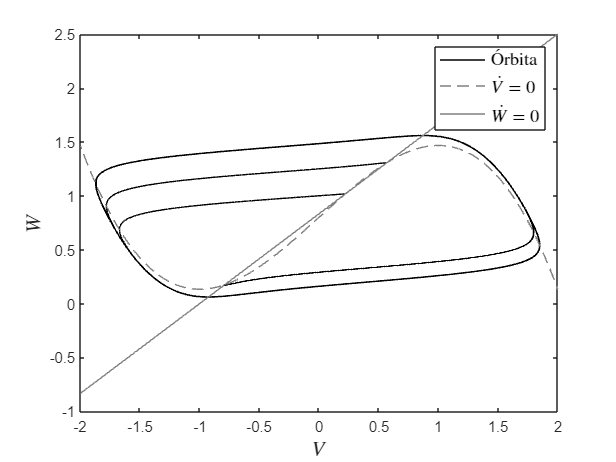

ta = 1000; n = 1000000; a = 1; b = 1.2; I = 0.8; phi = 0.08; y_0 = [-0.7914; 0.17380]; y_1 = [0.2218; 1.0182]; y_2 = [0.5696; 1.3080];
f = @(y) [y(1) - y(1).^3 / 3 - y(2) + I; 
          phi * (y(1) + a - b * y(2))];
[~, y0] = rk4(f, ta, y_0, n);
[~, y1] = rk4(f, ta, y_1, n);
[~, y2] = rk4(f, ta, y_2, n);

plot(y0(1, :), y0(2, :), 'k', 'LineWidth', 1.1); 

hold on;

h1 = plot(y1(1, :), y1(2, :), 'k'); 

plot(y2(1, :), y2(2, :), 'k'); 

y1_vals = linspace(min(y0(1, :)) - 1, max(y0(1, :)) + 1, 100000); 
y2_f1 = y1_vals - (y1_vals.^3 / 3) + I;
y2_f2 = (y1_vals + a) / b;

h2 = plot(y1_vals, y2_f1, '--', 'Color', [0.5, 0.5, 0.5]); 
h3 = plot(y1_vals, y2_f2, 'Color', [0.5, 0.5, 0.5]); 

xlim([-2, 2]);
ylim([-1, 2.5]);

xlabel('$V$', 'Interpreter', 'latex', 'FontSize', 14); 
ylabel('$W$', 'Interpreter', 'latex', 'FontSize', 14);

legend([h1, h2, h3], {'\''Orbita', '$\dot{V} = 0$', '$\dot{W} = 0$'}, 'Interpreter', 'latex', 'FontSize', 12);

hold off;

function [t, y] = rk4(f, ta, y0, n)
    h = ta / n;             
    t = linspace(0, ta, n+1);     
    y = zeros(length(y0), n+1);      
    y(:,1) = y0;            

    for i = 1:n
        k1 = f(y(:,i));  
        k2 = f(y(:,i) + (h/2) * k1);
        k3 = f(y(:,i) + (h/2) * k2);
        k4 = f(y(:,i) + h * k3);
        y(:,i+1) = y(:,i) + (h / 6) * (k1 + 2 * k2 + 2 * k3 + k4);
    end
end